% initialize the system parameters
param.g = 9.8;
param.h = 0.05;
param.dblAlt = 150;

% define the initial and final conditions:
xi = [0, 0, pi/2]; % [xi, yi, psi]
ui = [18, 0.5];     % [Vai(t), fii]
xf = [100, 100, 3*pi/4];
uf = [20, 0.6];
T = 100;

% initialize the time stamp, the state and input reference:
t = 1:0.1:100;
xi_ref = [];
u_ref = [];

% construct the matrix M alpha = bar{z} as in eq. (6):
M = [1 0 0 0 0 0 0 0 0 0 0 0;...
     0 1 0 0 0 0 0 0 0 0 0 0;...
     0 0 2 0 0 0 0 0 0 0 0 0;...
     0 0 0 0 0 0 1 0 0 0 0 0;...
     0 0 0 0 0 0 0 1 0 0 0 0;...
     0 0 0 0 0 0 0 0 2 0 0 0;...
     1 T T^2 T^3 T^4 T^5 0 0 0 0 0 0;...
     0 1 2*T 3*T^2 4*T^3 5*T^4 0 0 0 0 0 0;...
     0 0 2 2*3*T 3*4*T^2 4*5*T^3 0 0 0 0 0 0;...
     0 0 0 0 0 0 1 T T^2 T^3 T^4 T^5;...
     0 0 0 0 0 0 0 1 2*T 3*T^2 4*T^3 5*T^4;...
     0 0 0 0 0 0 0 0 2 2*3*T 3*4*T^2 4*5*T^3];

b = [xi(1); ui(1)*cos(xi(3)); -sin(xi(3))*param.g*tan(ui(2));...
     xi(2); ui(1)*sin(xi(3)); cos(xi(3))*param.g*tan(ui(2));...
     xf(1); uf(1)*cos(xf(3)); -sin(xf(3))*param.g*tan(uf(2));...
     xf(2); uf(1)*sin(xf(3)); cos(xf(3))*param.g*tan(uf(2))]

b =          0
    0.0000
   -5.3538
         0
   18.0000
    0.0000
  100.0000
  -14.1421
   -4.7408
  100.0000


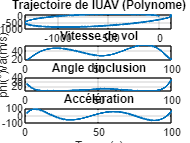


a = inv(M) * b;

% define the flat output and its derivatives
z1 = @(t) (a(1) + a(2)*t + a(3)*t.^2 + a(4)*t.^3 + a(5)*t.^4 + a(6)*t.^5);
z2 = @(t) (a(7) + a(8)*t + a(9)*t.^2 + a(10)*t.^3 + a(11)*t.^4 + a(12)*t.^5);
zd1 = @(t) (a(2) + 2*a(3)*t + 3*a(4)*t.^2 + 4*a(5)*t.^3 + 5*a(6)*t.^4);
zd2 = @(t) (a(8) + 2*a(9)*t + 3*a(10)*t.^2 + 4*a(11)*t.^3 + 5*a(12)*t.^4);
zdd1 = @(t) (2*a(3) + 2*3*a(4)*t + 3*4*a(5)*t.^2 + 4*5*a(6)*t.^3);
zdd2 = @(t) (2*a(9) + 2*3*a(10)*t + 3*4*a(11)*t.^2 + 4*5*a(12)*t.^3);

% define the state and input reference functions
X = @(t) [feval(z1, t); feval(z2, t); atan2(feval(zd2, t), feval(zd1, t))];
U = @(t) [sqrt(feval(zd1, t).^2 + feval(zd2, t).^2);...
    atan2(feval(zdd2, t).*feval(zd1, t) - feval(zd2, t).*feval(zdd1, t),...
    (param.g * sqrt(feval(zd1, t).^2 + feval(zd2, t).^2)))];

% compute the state and input reference:
tt = param.h:param.h:T;
xi_ref = [xi_ref feval(X, tt)];
u_ref = [u_ref feval(U, tt)];
x = z1(t);
y = z2(t);
psi = atan2(zd2(t), zd1(t));
Va = sqrt(zd1(t).^2 + zd2(t).^2);
phi = atan2(zdd2(t).*zd1(t)-zd2(t).*zdd1(t),param.g.*Va);
Acc = (zd1(t).*zdd1(t)+zd2(t).*zdd2(t)/sqrt(z1(t).^2+z2(t).^2));

%tracé des figures

subplot(4,1,1);
plot(x,y, 'LineWidth', 1.5);
xlabel('X(m)'); 
ylabel('Y(m)');
title('Trajectoire de lUAV (Polynome)');
grid on;

subplot(4,1,2);
plot(t, Va, 'LineWidth', 1.5);
xlabel('Temps(s)');
ylabel('Va(m/s)');
title('Vitesse de vol');
grid on;

subplot(4,1,3);
plot(t, rad2deg(phi), 'LineWidth', 1.5);
xlabel('Temps(s)');
ylabel('phi(°)');
title('Angle dinclusion');
grid on;

subplot(4,1,4);
plot(t, Acc, 'LineWidth', 1.5);
xlabel('Temps(s)');
ylabel('Acc(m/s^2)');
title('Accélération');
grid on;









% initialize the system parameters
param.g = 9.8;
param.h = 0.05;
param.dblAlt = 150;

% define the initial and final conditions:
xi = [0, 0, pi/2]; % [xi, yi, psi]
ui = [18, 0.5];     % [Vai(t), fii]
xf = [100, 100, 3*pi/4];
uf = [20, 0.6];
T = 100;

%% Calcul des points de contrôle Bézier
n = 5; % Degré de la courbe de Bézier
P_z1 = compute_bezier_control_points(xi, ui, xf, uf, param, n);
P_z2 = compute_bezier_control_points(xi, ui, xf, uf, param, n);

%% Calcul des trajectoires
t_normalized = linspace(0, 1, 100);
[z1, zd1, zdd1] = bezier_curve(t_normalized, P_z1, n);
[z2, zd2, zdd2] = bezier_curve(t_normalized, P_z2, n);

%% Post-traitement
tt = 0:param.h:T;
x = interp1(t_normalized*T, z1(:,1), tt);
y = interp1(t_normalized*T, z2(:,2), tt);
psi = atan2(interp1(t_normalized*T, zd2(:,2), tt), interp1(t_normalized*T, zd1(:,1), tt));
Va = sqrt(interp1(t_normalized*T, zd1(:,1), tt).^2 + interp1(t_normalized*T, zd2(:,2), tt).^2);
phi = atan2(interp1(t_normalized*T, zdd2(:,2), tt).*interp1(t_normalized*T, zd1(:,1), tt) - ...
      interp1(t_normalized*T, zd2(:,2), tt).*interp1(t_normalized*T, zdd1(:,1), tt), ...
      (param.g * Va));
Acc = (interp1(t_normalized*T, zd1(:,1), tt).*interp1(t_normalized*T, zdd1(:,1), tt) + ...
      interp1(t_normalized*T, zd2(:,2), tt).*interp1(t_normalized*T, zdd2(:,2), tt)) ./ Va;

%% Tracé des figures
figure;

subplot(4,1,1);
plot(x, y, 'LineWidth', 1.5);
xlabel('X (m)'); 
ylabel('Y (m)');
title('Trajectoire de l''UAV (Bézier)');
grid on;

subplot(4,1,2);
plot(tt, Va, 'LineWidth', 1.5);
xlabel('Temps (s)');
ylabel('Va (m/s)');
title('Vitesse de vol');
grid on;

subplot(4,1,3);
plot(tt, rad2deg(phi), 'LineWidth', 1.5);
xlabel('Temps (s)');
ylabel('phi (°)');
title('Angle d''inclinaison');
grid on;

subplot(4,1,4);
plot(tt, Acc, 'LineWidth', 1.5);
xlabel('Temps (s)');
ylabel('Acc (m/s^2)');
title('Accélération');
grid on;


function P = compute_bezier_control_points(xi, ui, xf, uf, param, n)
    
    % Points de contrôle initiaux et finaux
    P = zeros(n+1, 2);
    P(1,:) = [xi(1), xi(2)]; % Point de départ
    P(end,:) = [xf(1), xf(2)]; % Point d'arrivée
    
    % Calcul des dérivées initiales et finales
    zd1_0 = ui(1) * cos(xi(3)); % Vitesse initiale en x
    zd2_0 = ui(1) * sin(xi(3)); % Vitesse initiale en y
    zdd1_0 = -sin(xi(3)) * param.g * tan(ui(2)); % Accélération initiale en x
    zdd2_0 = cos(xi(3)) * param.g * tan(ui(2)); % Accélération initiale en y
    
    zd1_f = uf(1) * cos(xf(3)); % Vitesse finale en x
    zd2_f = uf(1) * sin(xf(3)); % Vitesse finale en y
    zdd1_f = -sin(xf(3)) * param.g * tan(uf(2)); % Accélération finale en x
    zdd2_f = cos(xf(3)) * param.g * tan(uf(2)); % Accélération finale en y
    
    % Calcul des points de contrôle intermédiaires
    P(2,:) = P(1,:) + [zd1_0 / n, zd2_0 / n]; % Point de contrôle pour la vitesse initiale
    P(end-1,:) = P(end,:) - [zd1_f / n, zd2_f / n]; % Point de contrôle pour la vitesse finale
    
    % Points de contrôle pour l'accélération initiale et finale
    P(3,:) = 2 * P(2,:) - P(1,:) + [zdd1_0 / (n*(n-1)), zdd2_0 / (n*(n-1))];
    P(end-2,:) = 2 * P(end-1,:) - P(end,:) + [zdd1_f / (n*(n-1)), zdd2_f / (n*(n-1))];
    
    % Points de contrôle intermédiaires (linéaires pour simplifier)
    for i = 4:n-2
        P(i,:) = P(i-1,:) + (P(end,:) - P(1,:)) / (n+1);
    end
end